## **Tutorial: Image Compression and Low t-rank Approximations with the t-SVDM**

Just like how we can do low-rank image compression for a normal 2D image, the t-SVDM can give low t-rank (tensor-rank, see []) approximations of a dataset. `tenOpt` allows us to find the optimal transformation resulting in the best (explain) low t-rank representation of the data.

First, go to [http://www.cad.zju.edu.cn/home/dengcai/Data/FaceData.html](http://www.cad.zju.edu.cn/home/dengcai/Data/FaceData.html) and select '64x64 Data File' under 'Yale database'. Place this file in the same working directory as this tutorial. Then, we can load the data:

rng(42);
dataset = load('Yale_64x64.mat');
fea = dataset.fea; % obtaining images from 'fea' field'
fea = fea / fronorm(fea); % normalizing images

This is a dataset of 165 images of faces. We're interested in finding the most dominant patterns in these images. In the matrix case, we'd want to vectorize each face, store them as columns of a matrix $\mathbf{A}$, and take the SVD of $\mathbf{A}$. For tensors, we keep the faces in the 2D $64\times64$ form, but we store them in the tensor as lateral slices (similar to columns in the tensor case):

% reshape into tensor
A = reshape(fea, [],64, 64);
A = permute(A, [3, 1, 2]); % faces oriented sideways
[n1,n2,n3] = size(A);

Let's also set some parameters:

k = 1;
imgIdx = 78;
rng(42);
showImg = @(x,i) imagesc(squeeze(x(:,i,:))');

Let's say we wanted to use a Discrete Cosine Transform (DCT) matrix as our transformation. First, let's get the t-SVDM of our data tensor: 

DCT = dctmtx(size(A,3));
[UDCT, SDCT, VDCT] = tSVDM(A, DCT, k);
DCTA = mprod(mprod(UDCT,SDCT,DCT), permute(VDCT,[2,1,3]),DCT);

Now, we can check to see how what kind of a rank-1 approximation we get for a particular image under this choice of transformation.

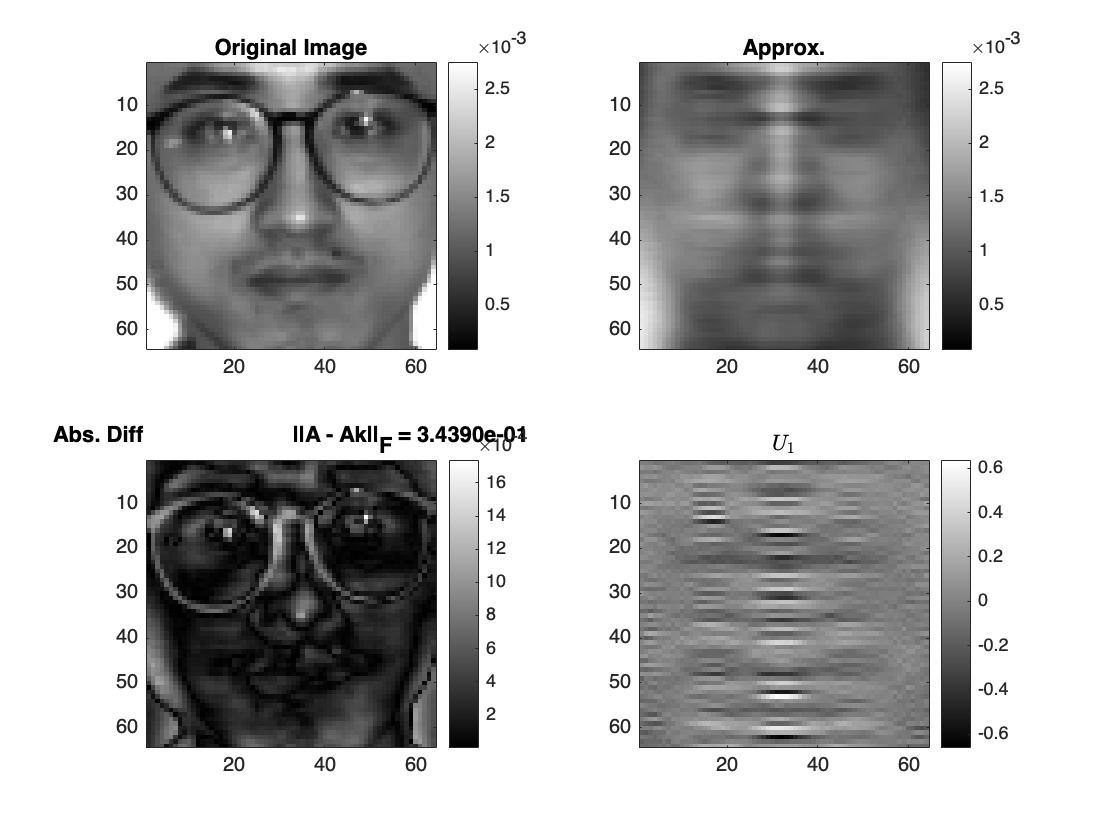

figure
subplot(2,2,1) 
showImg(A, imgIdx)
colorbar; colormap gray;
cax = clim();
title('Original Image');

subplot(2,2,2) 
showImg(DCTA, imgIdx)
colorbar; colormap gray
clim(cax);
title('Approx.');

subplot(2,2,3) 
showImg(abs(A - DCTA), imgIdx);
colorbar; colormap gray
title(sprintf('Abs. Diff\t\t||A - Ak||_F = %0.4e',fronorm(A - DCTA)));

subplot(2,2,4) 
showImg(UDCT,1)
colorbar; colormap gray
cax = clim();
title('Approx.');
title('$U_{1}$','Interpreter','latex')

TODO: Add Matrix Comparison

Now, let's find the optimal transformation that gives us the best t-rank $k$ approximated faces. First, we set the objective function and the optimizer:

fctn = objFctnLowRank(A,k,1);

opt = gradientDescent('verbose',1,'maxIter',1000,'manifold','Stiefel','logInterval',10);
opt.linesearch = armijoLinesearch('alpha',1e2,'manifold','Stiefel','gamma',1e-3,'maxIter',40);

We set our initial guess for $\mathbf{M}$ to be the identity matrix.

M0 = eye(n3);

Now, we can let the optimizer run until it converges to the optimal transformation.

[MSol,info] = opt.solve(fctn,M0);

iter        Jc          |dJc|       |dJc|/|dJ0| |x1-x0|     alphaLS     iterLS      flagLS      
0           5.98e-02    4.99e-03    1.00e+00    0.00e+00    1.00e+02    0           0           
10          5.76e-02    1.28e-02    2.55e+00    1.74e-01    5.00e+01    1           1           
20          5.69e-02    1.18e-02    2.37e+00    9.91e-02    2.50e+01    3           1           
30          5.65e-02    1.18e-02    2.36e+00    2.43e-02    2.50e+01    1           1           
40          5.63e-02    1.20e-02    2.40e+00    2.44e-02    1.25e+01    3           1           
50          5.62e-02    1.20e-02    2.41e+00    2.74e-02    2.50e+01    1           1           
60          5.61e-02    1.20e-02    2.41e+00    2.08e-02    1.25e+01    1           1           
70          5.59e-02    1.21e-02    2.41e+00    2.50e-02    1.25e+01    1           1           
80          5.58e-02    1.20e-02    2.40e+00    2.05e-02    1.25e+01    1           1           
90          5.57e-02    1.21e-

Using this optimal transformation $\mathbf{M}^{*}$, we can construct a low-rank approximation.

[USol,SSol,VSol] = tSVDM(A,MSol,k);
ASolk = mprod(USol,mprod(SSol,tran(VSol),MSol),MSol);

Let's look at the results using the transformation the optimizer found.

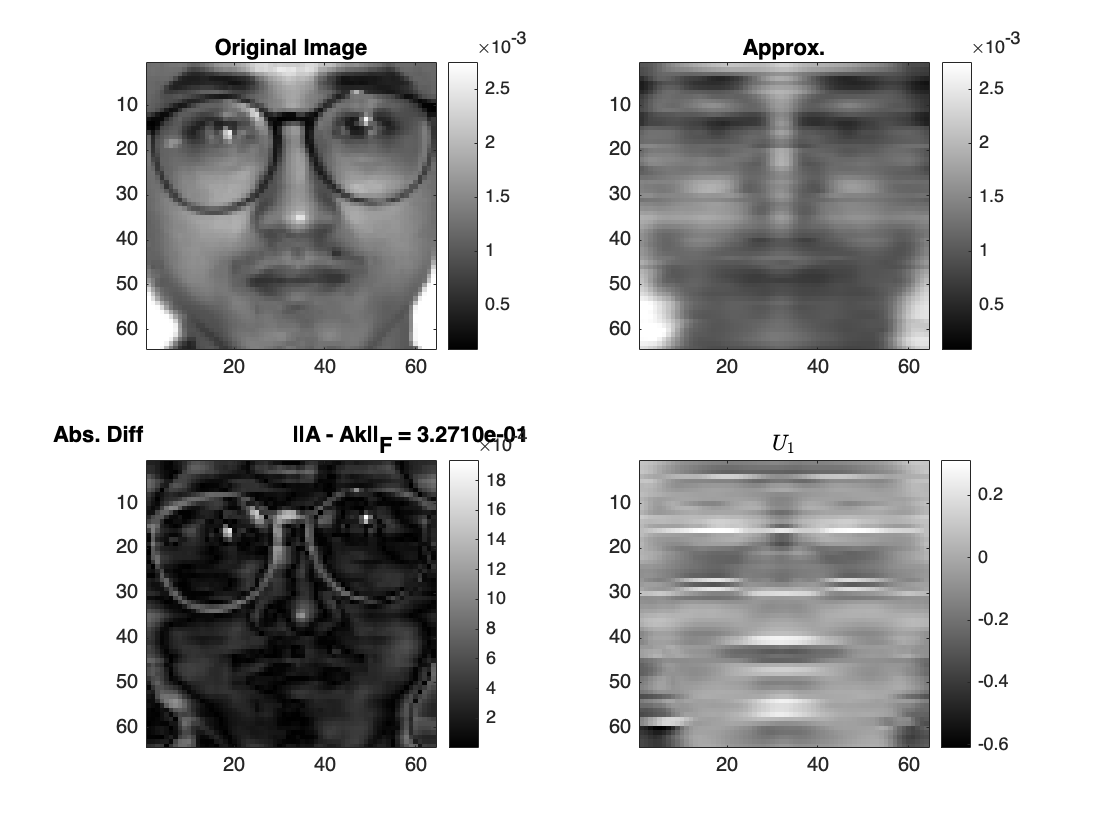

figure
subplot(2,2,1) 
showImg(A, imgIdx)
colorbar; colormap gray;
cax = clim();
title('Original Image');

subplot(2,2,2) 
showImg(ASolk, imgIdx)
colorbar; colormap gray
clim(cax);
title('Approx.');

subplot(2,2,3) 
showImg(abs(A - ASolk), imgIdx);
colorbar; colormap gray
title(sprintf('Abs. Diff\t\t||A - Ak||_F = %0.4e',fronorm(A - ASolk)));

subplot(2,2,4) 
showImg(USol,1)
colorbar; colormap gray
cax = clim();
title('Approx.');
title('$U_{1}$','Interpreter','latex')